Look at the Matlab codes 

% lec5_weak.m
% lec5_strong.m

Which produced the plots in Lecture 5, and make sure you understand what they are doing-- ask if anything is unclear. Note that $g(e+\Delta e) \approx g(e) + \Delta e g'(e)$, so that if $e$ is an estimate for $\mathbb{E}(f)$ with confidence interval $\pm 3 \sigma/\sqrt{N}$ then $g(e)$ is an estimate for $g(\mathbb{E}[f])$ with confidence interval $\pm 3 \sigma / \sqrt{N}) g'(e)$; this is used in 

% lec5_strong.m

to obtain a confidence interval for $\sqrt{\mathbb{E}[(\Delta S)^2 ]}$.

Convert the codes to C++, python or R if you wish. (For the C++ code, I suggest you create an output file with the results data which you can then read into Matlab or python to do the plotting.) Modify

% lec5_strong.m

 for the Heston stochastic volatility model which is a coupled pair of SDEs:


$$dS = rS dt + \sqrt{|v|} S dW^{(1)}$$



$$dv = \kappa ( \theta - v) dt + \xi \sqrt{|v|} dW^{(2)}$$


with $S(0) = 100$, $v(0) = 0.25$, $\theta = 0.25$, $\kappa = 2$, $\xi = 0.5$ over the time interval $[0, 1]$. The two driving Brownian motions are correlated so that


$$\mathbb{E}[dW^{(1)} dW^{(2)}] = -0.1 dt$$


so the correlation matrix is 


$$\Sigma = \pmatrix{1 & -0.1 \cr -0.1 & 1}$$


There is no (easy) exact solution in this case so just plot the comparison between the $h$ and $2h$ solutions. What is the order of strong convergence?

------------------------------------------------------------------------------------------------

Recall that we may decompose $W^{(2)}$ as:


$$W^{(2)}_t = \rho W^{(1)}_t + \sqrt{1-\rho^2} B_t$$


Where $\rho = -0.1$is the correlation of the two Brownian motions, and $B$ is a standard Brownian motion independent of $W^{(1)}$. We use this decomposition to give the correspoiding Euler-Maruyama updates for the Heston model:


$$S_{t_{n+1}} = r S_{t_n} h + \sqrt{|v_{t_n}|} S_{t_n} \Delta W_n$$



$$v_{t_{n+1}} = \kappa (\theta - v_{t_n}) h + \xi \sqrt{|v_{t_n}|} ( \rho \Delta W_n + \sqrt{1-\rho^2} \Delta B_n)$$


Where $t_{n+1}-t_n = h$ and $\Delta W_n, \Delta B_n$ are i.i.d $\mathcal{N}(0,h)$ random variables.

The following code is a modification of 

% lec5_strong

to approximate the Heston model:

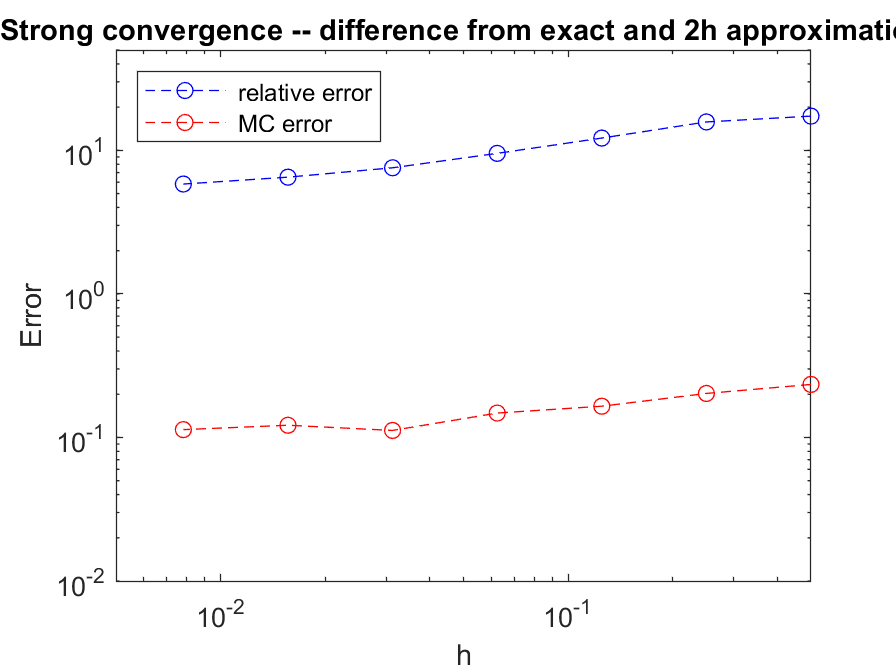

%
% Test strong convergence of Euler method
% for solving stochastic o.d.e.'s
%

% clear all; close all
randn('state',0)

addpath('..')

%
% problem parameters
%

r   = 0.05;
sig = 0.5;
T   = 1;
S0  = 100;

v0 = 0.25;
theta = 0.25;
kappa = 2;
xi = 0.5;
rho = -0.1;

%
% Monte Carlo simulation comparing to 2h simulation
%

M  = 1e+5;   % total number of Monte Carlo paths
M2 = 1e+4;   % number of paths at a time

for p = 1:7
    N = 2^p;
    h = T/N;
    
    sum1 = 0;
    sum2 = 0;
    sum3 = 0;
    sum4 = 0;
    
    for m = 1:M2:M
        m2 = min(M2,M-m+1);
        
        S  = S0*ones(1,m2);
        S2 = S0*ones(1,m2);
        
        v = v0*ones(1,m2);
        v2 = v0*ones(1,m2);
        
        %two indep brownian motions
        W  = 0;
        B  = 0;
        
        for n = 1:N/2
            %       S_old = S;
            %       v_old = v;
            
            %simulate 2 steps of size h
            dW1 = sqrt(h)*randn(1,m2);
            dB1 = sqrt(h)*randn(1,m2);
            
            S  = S.*(1+r*h+sqrt(abs(v)).*dW1);
            v = v + kappa*(theta-v)*h+xi*sqrt(abs(v)).*...
                (rho*dW1+ sqrt(1-rho^2)*dB1);
            
            dW2 = sqrt(h)*randn(1,m2);
            dB2 = sqrt(h)*randn(1,m2);
            
            S  = S.*(1+r*h+sqrt(abs(v)).*dW2);
            v = v + kappa*(theta-v)*h+xi*sqrt(abs(v)).*...
                (rho*dW2+ sqrt(1-rho^2)*dB2);
            
            %simulate 1 step of size 2h using the same increment
            S2  = S2.*(1+r*h+sqrt(abs(v2)).*(dW1+ dW2));
            v2 = v2 + kappa*(theta-v2)*h+xi*sqrt(abs(v2)).*...
                (rho*(dW1+ dW2)+ sqrt(1-rho^2)*(dB1+ dB2));
            
        end
        
        del  = (S2-S).^2;
        sum3 = sum3 + sum(del);
        sum4 = sum4 + sum(del.^2);
    end
    
    hh(p)   = h;
    
    Vd = sum3/M;
    sd = sqrt((sum4/M - (sum3/M)^2)/(M-1));
    err3(p) = sqrt(Vd);
    err4(p) = (0.5/sqrt(Vd)) * 3*sd;
end

figure; pos=get(gcf,'pos'); pos(3:4)=pos(3:4).*[0.8 0.8]; set(gcf,'pos',pos);
loglog(hh,abs(err3),'b--o',hh,err4,'r--o')
title('Strong convergence -- difference from exact and 2h approximation')
xlabel('h'); ylabel('Error');
legend(' relative error',' MC error','Location','NorthWest')
axis([.005 0.5 0.01 50])
print('-deps2c','lec7c.eps')